% The first demo code for ECE451 2022

% plot voltage waveforms. show rms values. show phase shifts

clear all
close all
clc

f = 60 % frequency

f = 60

w = 2*pi*f

w = 376.9911

Tcycle = 1/60

Tcycle = 0.0167

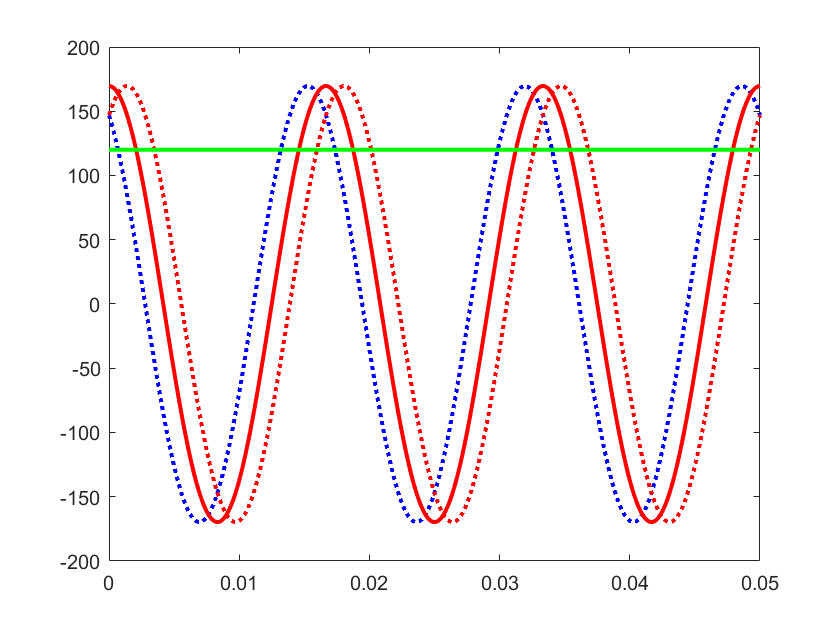


delta_T = 1/f/100;
length_T = 1/f*3;
t = [0:delta_T:length_T]';

Va_rms = 120; %in volt
Va = Va_rms*sqrt(2)*cos(w*t +0); %angle is in radians. 
% Va = Va_rms*sqrt(2)*cosd(w*t + 0); %angle is in degree. 
% Va = Va_rms*sqrt(2)*cosd(w*t + 30); %angle is in degree. 

Va_DC = Va_rms*ones(length(t),1);

figure(1)
plot(t,Va,'r','LineWidth',2)
hold on
plot(t, Va_DC,'g','LineWidth',2)